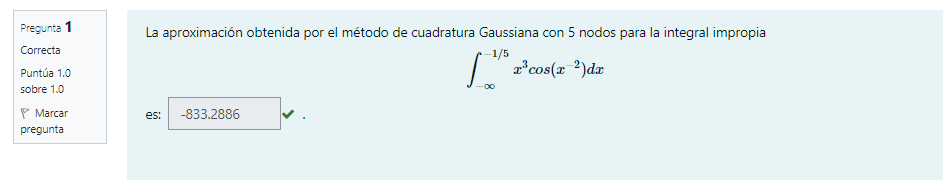

% INTEGRAL IMPROPIA
syms x
f = x^3*cos(x^(-2));
f = matlabFunction(f,"vars",{x});
a=-inf;
b=-1/5;
N = 5 % Cantidad de nodos;
[quad, raices, nodos, coefs] = impropias(f, a, b, N) %Esta funcion calcula integrales
%Impropias

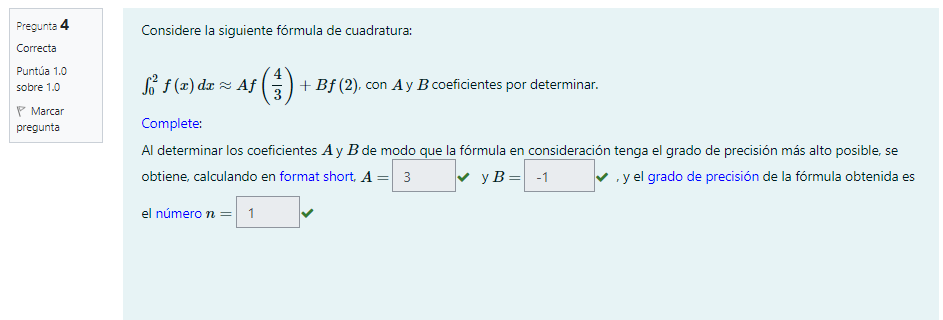

% CALCULO GRADO DE PRECISION

n=1000;
syms x
a=0;b=2; %Limites de integracion
for k=0:n
    g= x^k;
    if k==0
        f= @(x) 1;
    else
        f=matlabFunction(g);
    end
    aprox=(1*f(4/3)-f(2)); % Aqui se reemplazan los valores de A y B y la funcion
    int(g,a,b);
    if int(g,a,b)==aprox
        continue
    else
        break
    end
end
if k==0
    grado_de_precision=0
else
    grado_de_precision=k-1
end

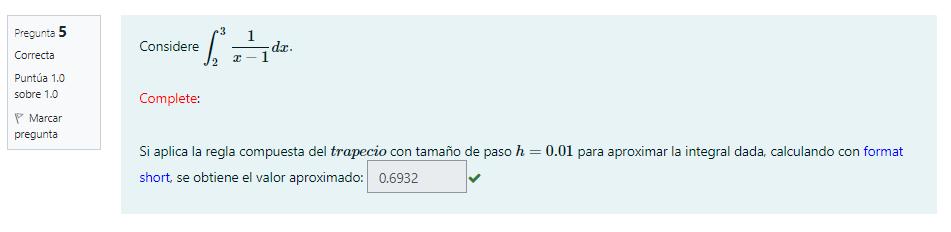

syms x
f = 1/(x-1)

$$f = \frac{1}{x-1}$$

f = matlabFunction(f,'Vars',{x});
a=2;b=3;
% h = (b-a)/n se calcula n y ya con esto se reemplaza

M = 100

s = traprl (f, a, b, 100) 

s = 0.6932